labels = h5read("data_pipeline/bolete_lowres.h5", "/bolete-labels");
edibility = h5read("data_pipeline/bolete_lowres.h5", "/bolete-edibility");
characteristics = h5read("data_pipeline/bolete_lowres.h5", "/bolete-characteristics");

mode_id = mode(labels)

mode_id = uint64
11

rand_sp = nnz(labels == mode_id) / length(labels)

rand_sp = 0.0161

[~, edibility_id] = max(edibility,[],2);
mode_ed = mode(edibility_id)

mode_ed = 4

rand_ed = nnz(edibility_id == mode_ed) / size(edibility_id,1)

rand_ed = 0.5439

mode_c = mode(characteristics)

mode_c = 1×38 uint8 row vector
   0   1   1   1   0   1   0   0   0   0   0   1   0   1   0   1   0   0   1   1   0   1   0   1   1   0   0   0   0   0   0   0   0   1   1   1   0   0


rand_c = nnz(characteristics == mode_c) / size(characteristics,1) / size(characteristics, 2)

rand_c = 0.7062

tl = readmatrix("performance_data/direct_ed_bolete_lowres.h5_ed_perform.csv")'

tl =          0    0.5562
    0.0100    0.5562
    0.0200    0.5562
    0.0300    0.5562
    0.0400    0.5562
    0.0500    0.5562
    0.0600    0.5562
    0.0700    0.5562
    0.0800    0.5562
    0.0900    0.5562


th = readmatrix("performance_data/direct_ed_bolete.h5_ed_perform.csv")'

th =          0    0.5562
    0.0100    0.5562
    0.0200    0.5562
    0.0300    0.5562
    0.0400    0.5562
    0.0500    0.5562
    0.0600    0.5562
    0.0700    0.5562
    0.0800    0.5562
    0.0900    0.5562


trueL = readmatrix("evaluation_data/direct_ed_bolete_lowres.h5_true.csv");
predL = readmatrix("evaluation_data/direct_ed_bolete_lowres.h5_pred.csv");
nnz(trueL==predL) / length(trueL)

ans = 0.5561

trueH = readmatrix("evaluation_data/direct_ed_bolete.h5_true.csv");
predH = readmatrix("evaluation_data/direct_ed_bolete.h5_pred.csv");
nnz(trueH==predH) / length(trueH)

ans = 0.5561

nnz(predL ~= predH) / length(trueH)

ans = 0.0945

nnz(trueL == trueH) / length(trueH)

ans = 1

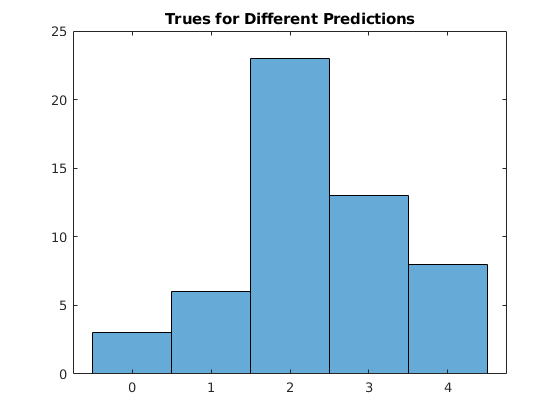

histogram(trueL(predL ~= predH))
title("Trues for Different Predictions")

num_different = nnz(predH ~= trueH)

num_different = 249

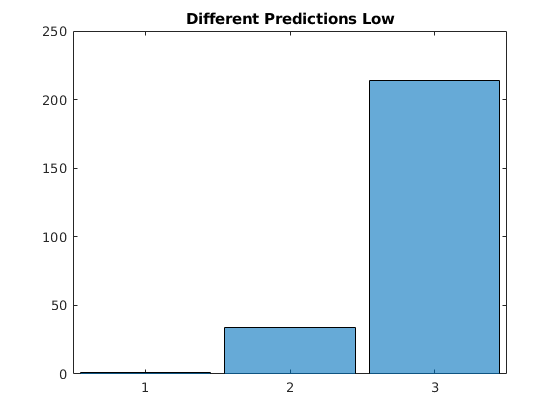

histogram(categorical(predL(predL ~= trueL)))
title("Different Predictions Low")

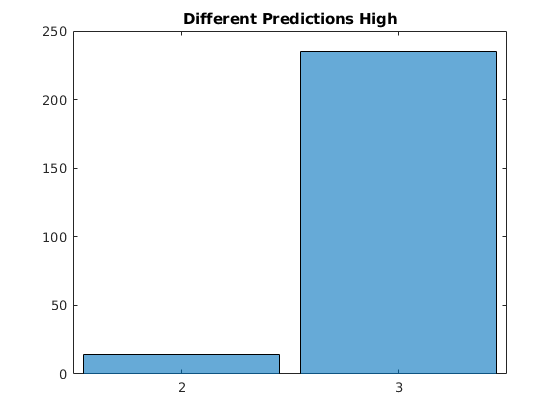

histogram(categorical(predH(predH ~= trueH)))
title("Different Predictions High")

num_diff_mistakes = nnz(xor((predL ~= trueL), (predH ~= trueH)))

num_diff_mistakes = 36